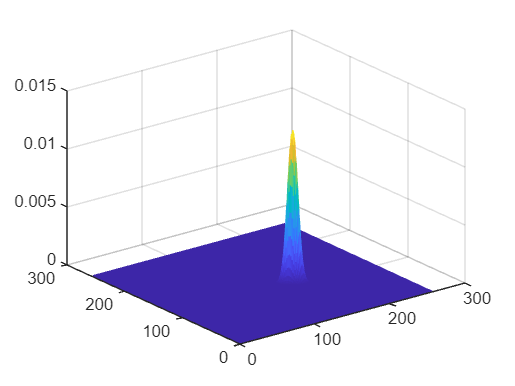

model = createSkinModel('model_skory.bmp');
mesh(model);

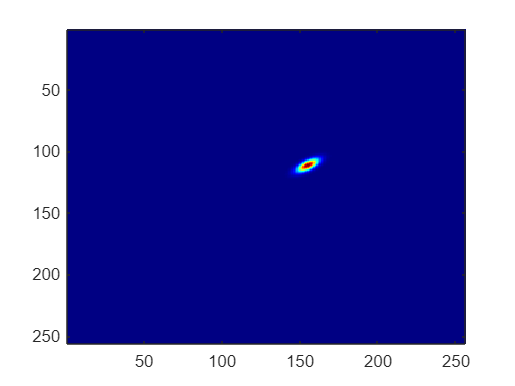


figure;imagesc(model);colormap(jet);

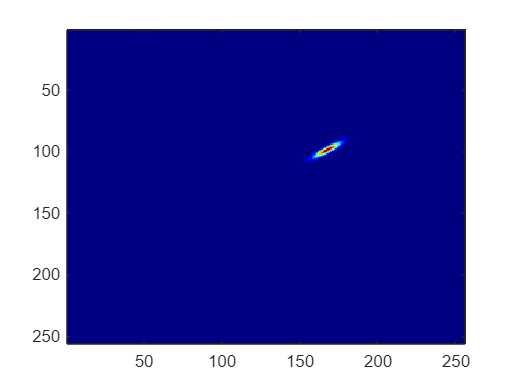

figure;imagesc(model2);colormap(jet)

Detekcja Twarzy

addpath('BazaObrazow');
testowy = imread('testowy_0_0000.jpeg');

figure, subplot(2,3,1), imshow(testowy);
szary = probabilityIM(testowy, model2);
subplot(2,3,2), imshow(szary, []);
colormap(gray);

binaryzacja

level = 0.0011227 %1 próg binaryzacji

level = 0.0011

binary = im2bw(szary, level);
subplot(2, 3, 3), imshow(binary);

Zamkniecie

se = strel('disk', 6); %2 obiekt strukturalny dysk r=6
zamkniety = imclose(binary, se)

zamkniety = 576×768 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

subplot(2, 3, 4), imshow(zamkniety)

label1 = bwlabel(zamkniety);
res = regionprops(label1);

[res.Area]

ans =            8          71           2          40         152          30       70541          10           8


wyczyszczony = bwareaopen(zamkniety, 400);% minimalna wielkość 400
subplot(2,3,5), imshow(wyczyszczony);

szukanie twarzy

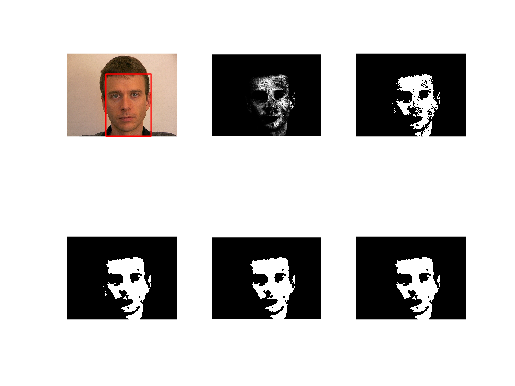

[x1, x2, twarz] = szukaj_twarz(wyczyszczony);
subplot(2,3,6), imshow(twarz);

subplot(2,3,1)
pos=[x1(2) x1(1) x2(2)-x1(2) x2(1)-x1(1)];
hold on;rectangle('Position',pos,'EdgeColor','red'); hold off

obraz testowy2

testowy2 = imread('testowy_3_0003.jpeg');

figure, subplot(2,3,1), imshow(testowy2);
szary2 = probabilityIM(testowy2, model2);
subplot(2,3,2), imshow(szary2, []);
colormap(gray);

level2 = 0.00082861 %1 próg

level2 = 8.2861e-04

binary2 = im2bw(szary2, level2);
subplot(2, 3, 3), imshow(binary2);

se2 = strel('disk', 6); %2 obiekt ten sam dysk r=6
zamkniety2 = imclose(binary2, se2)

zamkniety2 = 576×768 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

subplot(2, 3, 4), imshow(zamkniety2)

label2 = bwlabel(zamkniety2);
res2 = regionprops(label2);

[res.Area]

ans =            8          71           2          40         152          30       70541          10           8


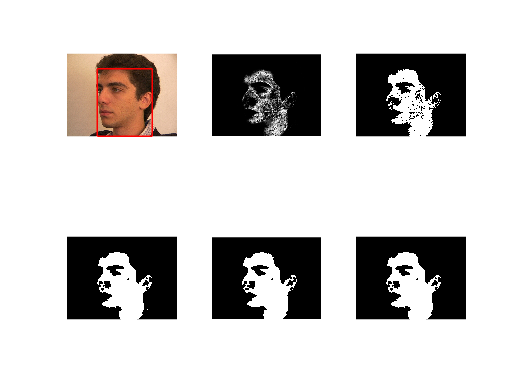

wyczyszczony2 = bwareaopen(zamkniety2,400); % minimalna wielkość bez zmian
subplot(2,3,5), imshow(wyczyszczony2);

[x12, x22, twarz2] = szukaj_twarz(wyczyszczony2);
subplot(2,3,6), imshow(twarz2);

subplot(2,3,1)
pos=[x12(2) x12(1) x22(2)-x12(2) x22(1)-x12(1)];
hold on;rectangle('Position',pos,'EdgeColor','red'); hold off

obraz testowy 3

testowy3 = imread('testowy_7_0003.jpeg');

figure, subplot(2,3,1), imshow(testowy3);
szary3 = probabilityIM(testowy3, model2);
subplot(2,3,2), imshow(szary3, []);
colormap(gray);

level3 = 0.00016572 %1 próg

level3 = 1.6572e-04

binary3 = im2bw(szary3, level3);
subplot(2, 3, 3), imshow(binary3);

se3 = strel('disk', 6); %2 obiekt ten sam dysk r=6
zamkniety3 = imclose(binary3, se3)

zamkniety3 = 1536×2048 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

subplot(2, 3, 4), imshow(zamkniety3)

label3 = bwlabel(zamkniety3);
res3 = regionprops(label3);

[res.Area]

ans =            8          71           2          40         152          30       70541          10           8


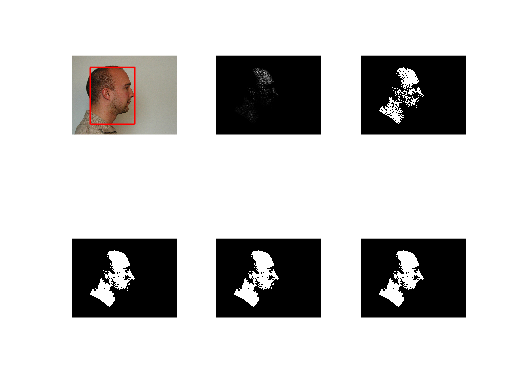

wyczyszczony3 = bwareaopen(zamkniety3,400); % minimalna wielkość bez zmian
subplot(2,3,5), imshow(wyczyszczony3);

[x1, x2, twarz3] = szukaj_twarz(wyczyszczony3);
subplot(2,3,6), imshow(twarz3);

subplot(2,3,1)
pos=[x1(2) x1(1) x2(2)-x1(2) x2(1)-x1(1)];
hold on;rectangle('Position',pos,'EdgeColor','red'); hold off

Obserwacje:

Jedynym problemem było odpowiednie dobranie progu binaryzacji, który rzeczywiście należało ustalić dość dokładnie. Pozostałe parametry bez zmian okazały się wystarczające.

Część 2

addpath('BazaObrazow');
testowy = imread('testowy_0_0001.jpeg');
faceDetector = vision.CascadeObjectDetector();

bbox = step(faceDetector, testowy)

bbox =    150    72   368   368


Out = insertObjectAnnotation(testowy, 'rectangle', bbox, 'Twarz')

Out = 576×768×3 uint8 array
Out(:,:,1) =

   165   160   161   165   167   168   171   171   169   167   170   173   173   174   174   172   177   174   174   178   180   180   181   181   181   178   175   170   172   166   163   160   160   149   130   104   100   102    88    89    86    89    88    69    54    50    57    51    54    56    54    50    50    54    56    54    45    55    57    56    52    45    41    41    43    41    41    40    40    29    26    26    29    27    26    27    26    19    20    28    24    29    41    43    47    43    39    36    32    37    37    40    42    37    38    40    33    29    29    30    33    32    34    37    32    27    26    31    31    37    41    52    47    44    39    40    42    43    40    39    43    41    36    31    33    37    39    38    35    35    37    41    44    41    37    39    36    37    29    24    29    29    34    40    42    40    43    44    44    43    38    32    39    45    48    49    46    42    41    

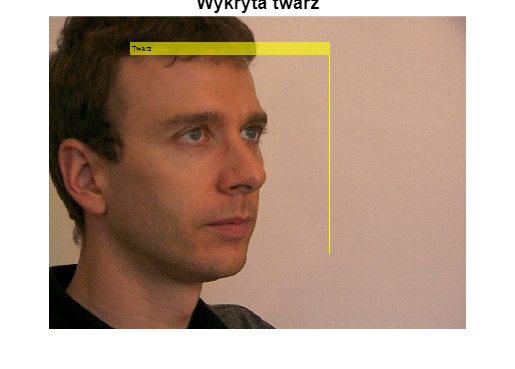

figure, imshow(Out), title('Wykryta twarz');

test dla wszystkich plików:

%addpath('BazaObrazow');
files = dir('BazaObrazow/*.jpeg');
not_found = 0;
found = 0;
for i = 1:numel(files);
  filename = files(i).name;
  testowy = imread(filename);

  faceDetector = vision.CascadeObjectDetector();
  bbox = step(faceDetector, testowy);

    if isempty(bbox)
        not_found = not_found + 1;
    else
        found = found + 1;
    end

end
found

found = 35

not_found

not_found = 18

ratio = found / (found + not_found) * 100

ratio = 66.0377

znaleziono 35 twarzy

na 18 obrazkach nie znaleziono

sukces w 66.0377% przypadków

## Podsumowanie

#### Rezultaty

rezultaty są uwzględnione w kodzie powyżej, w komentarzach i tekstach między komórkami

#### Analiza i wnioski

Wyznaczanie modelu koloru skóry

- Wczytanie obrazu RGB, raczej oczywiste, z czegoś musimy pobrać próbkę

- Przekształcenie obrazu do YCbCr i pobranie składowych chrominacji, będzie nam to potrzebne ponieważ skóra przeważnie różni się luminacją, więc nasz model będzie się dobrze sprawdzał dla wszystkich przypadków

- Wyznaczenie funkcji gęstości prawdopodobieństwa, jest ona wykorzystywana do decydowania czy fragment obrazu należy do twarzy

Zamknięcie to kolejne wykonanie dylatacji i erozji na obrazie, pozwala ono na usunięcie zakłóceń, oraz złączenie rozłączonych obszarów twarzy.

Według prostych obliczeń przeprowadzonych powyżej, algorytm Haara był w stanie znaleźć twarz w ok. 66% przypadków.

#### Pytania

- Sieci konwolucyjne (CNN), Eigenfaces, Fisherfaces, Local Binary Patterns

- Kaskady Haara: Okno przebiega po obrazie, jeśli nie znajdzie obiektu to idzie dalej, w przypadku gdy klasyfikator doszuka się obiektu, wysyła go do kolejnego klasyfikatora, dopiero gdy przejdzie przez wszystkie, może zostać ostatecznie uznany za obiekt poszukiwań.